## EEL839 - Transmissão Digital

## Parte 2 - Treinamento da rede neural e ataque FGSM

Trabalho sobre o artigo: Adversarial training based channel estimation to mitigate jamming attacks in OFDM systems

Guilherme Araujo Thomaz

Este código implementa a parte do trabalho referente à geração de gráficos.

## 1 - Estimação por LS

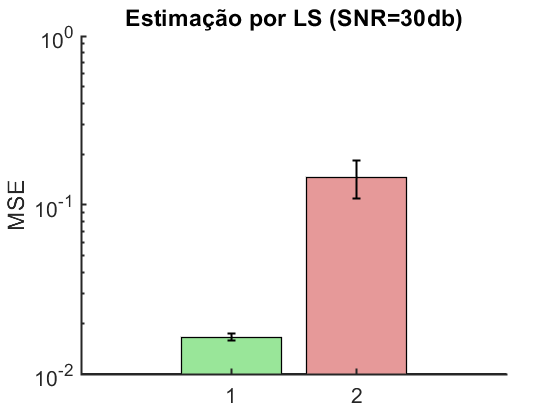

%X = categorical({'Pubicação insegura','Publicação segura','Consulta insegura','Consulta segura'});
%X = reordercats(X,{'Pubicação insegura','Publicação segura','Consulta insegura','Consulta segura'});
X = [1 2];
Y = [0.0165 0.1454];
erro = [7.93e-4 0.0368];
hbar = bar(X,Y,'FaceColor','flat');
hbar.CData(2,:) = [.9 0.6 .6];
hbar.CData(1,:) = [.6 0.9 .6];
hbar.LineWidth = 1;
ylim([10e-3 1])
set(gca,'YScale','log')
hold on
err = errorbar(Y,erro);
err.LineWidth = 1.5;
err.Color = [0 0 0];
err.LineStyle = 'none';
t = title('Estimação por LS (SNR=30db)');
t.FontSize = 16;
yl = ylabel('MSE');
yl.FontSize = 16;
yl.FontSize = 16;
H=gca;
H.LineWidth = 1.5;
set(gca,'FontSize',16)
box off
hold off

## 2 - Rede neural vulnerável

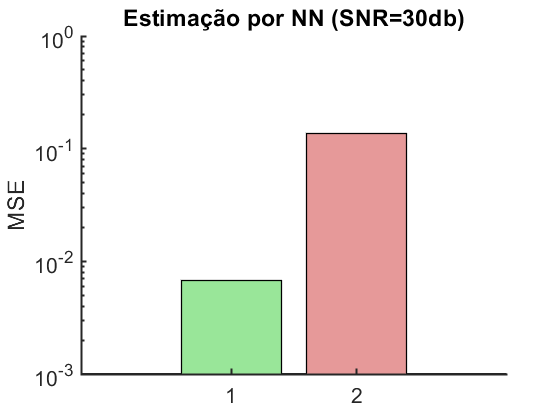

%X = categorical({'Pubicação insegura','Publicação segura','Consulta insegura','Consulta segura'});
%X = reordercats(X,{'Pubicação insegura','Publicação segura','Consulta insegura','Consulta segura'});
X = [1 2];
Y = [0.0068 0.1356];
hbar = bar(X,Y,'FaceColor','flat');
hbar.CData(2,:) = [.9 0.6 .6];
hbar.CData(1,:) = [.6 0.9 .6];
hbar.LineWidth = 1;
ylim([10e-4 1])
set(gca,'YScale','log')
hold on
t = title('Estimação por NN (SNR=30db)');
t.FontSize = 16;
yl = ylabel('MSE');
yl.FontSize = 16;
yl.FontSize = 16;
H=gca;
H.LineWidth = 1.5;
set(gca,'FontSize',16)
box off
hold off

## 3 - Variação da SNR

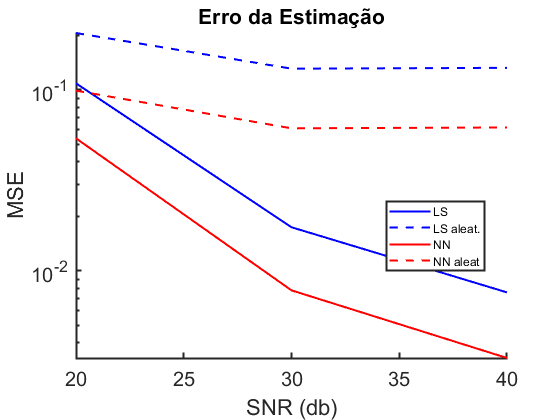

X = [20 30 40];
ls = [0.1084 0.0174 0.0076];
ls_rand = [0.2057 0.1307 0.1321];
nn = [0.0539 0.0078 0.0033];
nn_rand = [0.0988 0.0612 0.0619];

% Defina cores personalizadas para cada linha
cor_ls = 'b';         % Azul
cor_ls_rand = 'b';    
cor_nn = 'r';         % Vermelho
cor_nn_rand = 'r';    

figure;

% Plote as curvas com as cores personalizadas e escala logarítmica no eixo y
semilogy(X, ls, 'LineWidth', 1.5, 'Color', cor_ls);
hold on;
semilogy(X, ls_rand, 'LineWidth', 1.5, 'Color', cor_ls_rand, 'LineStyle', '--');
semilogy(X, nn, 'LineWidth', 1.5, 'Color', cor_nn);
semilogy(X, nn_rand, 'LineWidth', 1.5, 'Color', cor_nn_rand, 'LineStyle', '--');

t = title('Erro da Estimação');
t.FontSize = 16;

x = xlabel('SNR (db)');
x.FontSize = 16;

y = ylabel('MSE');
y.FontSize = 16;

% Aumente a espessura das linhas dos eixos
ax = gca;
ax.LineWidth = 1.5;

ax.XAxis.FontSize = 15;
ax.YAxis.FontSize = 15;


box off

% Adicione uma legenda
legend('LS', 'LS aleat.', 'NN', 'NN aleat', 'Location', 'Best');

## 4 - Variação da potência do ruído de ataque

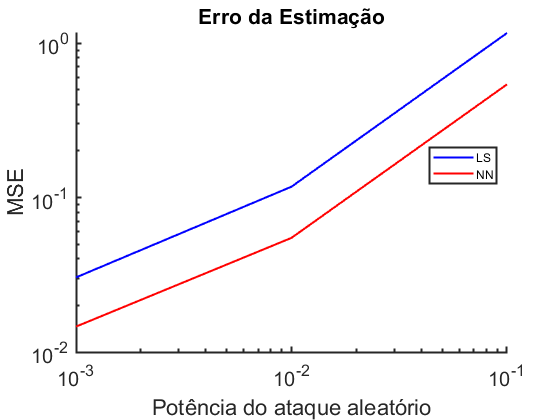

X = [10^-3 10^-2 10^-1];
ls = [0.0304 0.1175 1.1609];
nn = [0.0146 0.0548 0.5398];

% Defina cores personalizadas para cada linha
cor_ls = 'b';         % Azul
cor_nn = 'r';         % Vermelho

figure;

% Plote as curvas com as cores personalizadas e escala logarítmica no eixo y
loglog(X, ls, 'LineWidth', 1.5, 'Color', cor_ls);
hold on;
loglog(X, nn, 'LineWidth', 1.5, 'Color', cor_nn);

t = title('Erro da Estimação');
t.FontSize = 16;

x = xlabel('Potência do ataque aleatório');
x.FontSize = 16;

y = ylabel('MSE');
y.FontSize = 16;

% Aumente a espessura das linhas dos eixos
ax = gca;
ax.LineWidth = 1.5;

ax.XAxis.FontSize = 15;
ax.YAxis.FontSize = 15;

box off

% Adicione uma legenda
legend('LS', 'NN', 'Location', 'Best');
hold off

## 5 - Ataque FGSM

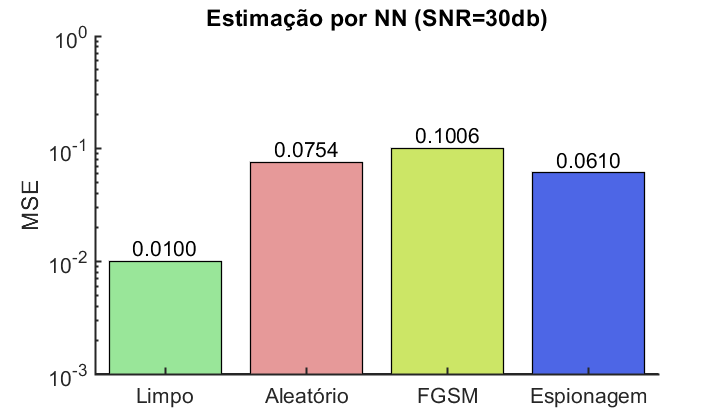

figure;
X = categorical({'Limpo', 'Aleatório', 'FGSM', 'Espionagem'});
%Y = [0.0068 0.1356 0.0688];
X = reordercats(X, {'Limpo', 'Aleatório', 'FGSM', 'Espionagem'});
Y = [0.0100 0.0754 0.1006 0.0610];
hbar = bar(X,Y,'FaceColor','flat');
hbar.CData(2,:) = [.9 0.6 .6];
hbar.CData(1,:) = [.6 0.9 .6];
hbar.CData(3,:) = [.8 0.9 .4];
hbar.CData(4,:) = [.3 0.4 .9];
hbar.LineWidth = 1;
ylim([10e-4 1])
set(gca,'YScale','log')
hold on
t = title('Estimação por NN (SNR=30db)');
t.FontSize = 16;
yl = ylabel('MSE');
yl.FontSize = 16;
yl.FontSize = 16;
H=gca;
H.LineWidth = 1.5;
set(gca,'FontSize',16)

% Adicione os valores acima de cada barra
for i = 1:numel(Y)
    text(X(i), Y(i), num2str(Y(i), '%.4f'), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', 'FontSize', 16);
end

fig = gcf;
fig.Position(3) = fig.Position(3) * 1.3; % Ajuste o fator conforme necessário

box off
hold off

## 6 - FGSM 2

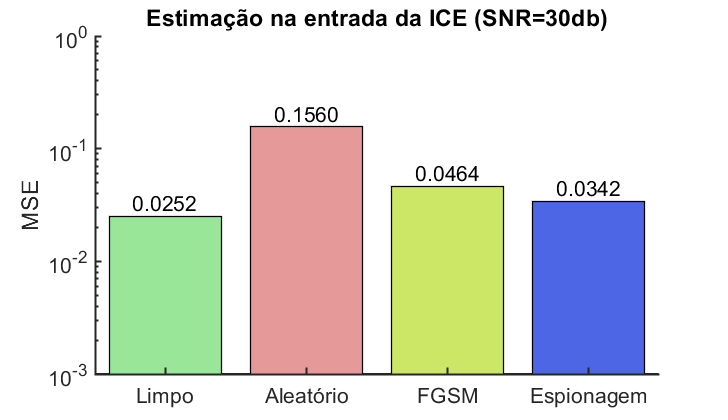

figure;
X = categorical({'Limpo', 'Aleatório', 'FGSM', 'Espionagem'});
%Y = [0.0068 0.1356 0.0688];
X = reordercats(X, {'Limpo', 'Aleatório', 'FGSM', 'Espionagem'});
Y = [0.0252 0.1560 0.0464 0.0342];
hbar = bar(X,Y,'FaceColor','flat');
hbar.CData(2,:) = [.9 0.6 .6];
hbar.CData(1,:) = [.6 0.9 .6];
hbar.CData(3,:) = [.8 0.9 .4];
hbar.CData(4,:) = [.3 0.4 .9];
hbar.LineWidth = 1;
ylim([10e-4 1])
set(gca,'YScale','log')
hold on
t = title('Estimação na entrada da ICE (SNR=30db)');
t.FontSize = 16;
yl = ylabel('MSE');
yl.FontSize = 16;
yl.FontSize = 16;
H=gca;
H.LineWidth = 1.5;
set(gca,'FontSize',16)

% Adicione os valores acima de cada barra
for i = 1:numel(Y)
    text(X(i), Y(i), num2str(Y(i), '%.4f'), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', 'FontSize', 16);
end

fig = gcf;
fig.Position(3) = fig.Position(3) * 1.3; % Ajuste o fator conforme necessário

box off
hold off

## 7 - Treinamento Adversarial Típico

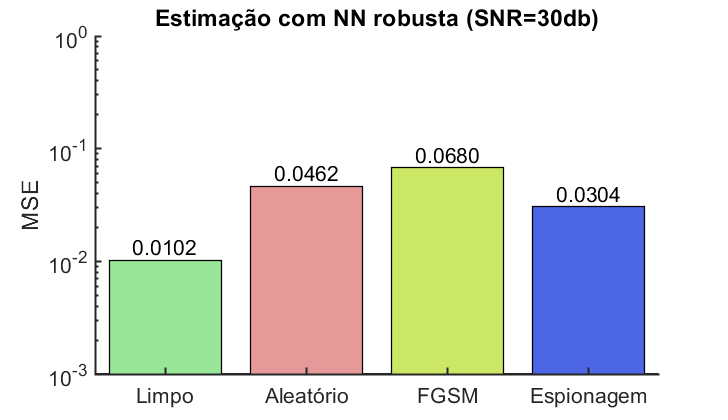

figure;
X = categorical({'Limpo', 'Aleatório', 'FGSM', 'Espionagem'});
%Y = [0.0068 0.1356 0.0688];
X = reordercats(X, {'Limpo', 'Aleatório', 'FGSM', 'Espionagem'});
Y = [0.0102 0.0462 0.0680 0.0304];
hbar = bar(X,Y,'FaceColor','flat');
hbar.CData(2,:) = [.9 0.6 .6];
hbar.CData(1,:) = [.6 0.9 .6];
hbar.CData(3,:) = [.8 0.9 .4];
hbar.CData(4,:) = [.3 0.4 .9];
hbar.LineWidth = 1;
ylim([10e-4 1])
set(gca,'YScale','log')
hold on
t = title('Estimação com NN robusta (SNR=30db)');
t.FontSize = 16;
yl = ylabel('MSE');
yl.FontSize = 16;
yl.FontSize = 16;
H=gca;
H.LineWidth = 1.5;
set(gca,'FontSize',16)

% Adicione os valores acima de cada barra
for i = 1:numel(Y)
    text(X(i), Y(i), num2str(Y(i), '%.4f'), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', 'FontSize', 16);
end

fig = gcf;
fig.Position(3) = fig.Position(3) * 1.3; % Ajuste o fator conforme necessário

box off
hold off

## 8 - Treinamento Adversarial Proposto

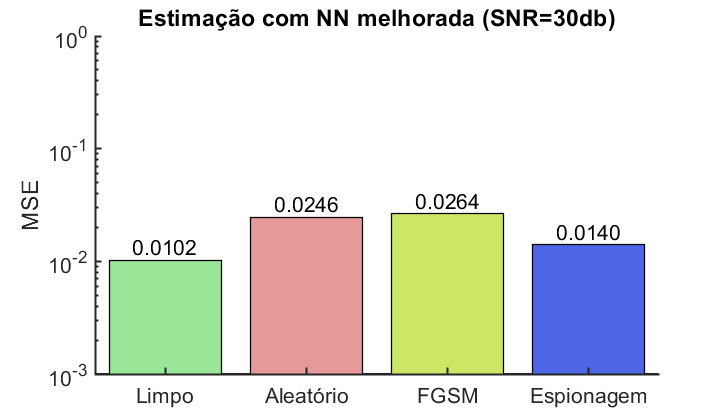

figure;
X = categorical({'Limpo', 'Aleatório', 'FGSM', 'Espionagem'});
%Y = [0.0068 0.1356 0.0688];
X = reordercats(X, {'Limpo', 'Aleatório', 'FGSM', 'Espionagem'});
Y = [0.0102 0.0246 0.0264 0.0140];
hbar = bar(X,Y,'FaceColor','flat');
hbar.CData(2,:) = [.9 0.6 .6];
hbar.CData(1,:) = [.6 0.9 .6];
hbar.CData(3,:) = [.8 0.9 .4];
hbar.CData(4,:) = [.3 0.4 .9];
hbar.LineWidth = 1;
ylim([10e-4 1])
set(gca,'YScale','log')
hold on
t = title('Estimação com NN melhorada (SNR=30db)');
t.FontSize = 16;
yl = ylabel('MSE');
yl.FontSize = 16;
yl.FontSize = 16;
H=gca;
H.LineWidth = 1.5;
set(gca,'FontSize',16)

% Adicione os valores acima de cada barra
for i = 1:numel(Y)
    text(X(i), Y(i), num2str(Y(i), '%.4f'), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', 'FontSize', 16);
end

fig = gcf;
fig.Position(3) = fig.Position(3) * 1.3; % Ajuste o fator conforme necessário

box off
hold off

## 9 - SNR NN vulnerável

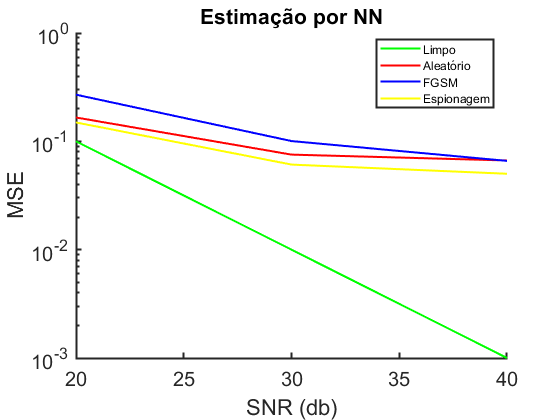

figure;
X = [20 30 40];
nn = [0.1 0.01 0.001];
nn_rand = [0.1660 0.0754 0.0666];
nn_fgsm = [0.2696 0.1006 0.0660];
nn_espio = [0.1494 0.0610 0.0502];

% Defina cores personalizadas para cada linha
cor_nn = 'g';         % Vermelho
cor_nn_rand = 'r'; 
cor_nn_fgsm = 'b'; 
cor_nn_espio = 'y'; 

figure;

% Plote as curvas com as cores personalizadas e escala logarítmica no eixo y
semilogy(X, nn, 'LineWidth', 1.5, 'Color', cor_nn);
hold on;
semilogy(X, nn_rand, 'LineWidth', 1.5, 'Color', cor_nn_rand);
semilogy(X, nn_fgsm, 'LineWidth', 1.5, 'Color', cor_nn_fgsm);
semilogy(X, nn_espio, 'LineWidth', 1.5, 'Color', cor_nn_espio);

t = title('Estimação por NN');
t.FontSize = 16;

x = xlabel('SNR (db)');
x.FontSize = 16;

y = ylabel('MSE');
y.FontSize = 16;
ylim([10e-4 1])

% Aumente a espessura das linhas dos eixos
ax = gca;
ax.LineWidth = 1.5;

ax.XAxis.FontSize = 15;
ax.YAxis.FontSize = 15;


box off

% Adicione uma legenda
legend('Limpo', 'Aleatório', 'FGSM', 'Espionagem', 'Location', 'Best');

## 10 - SNR NN robusta

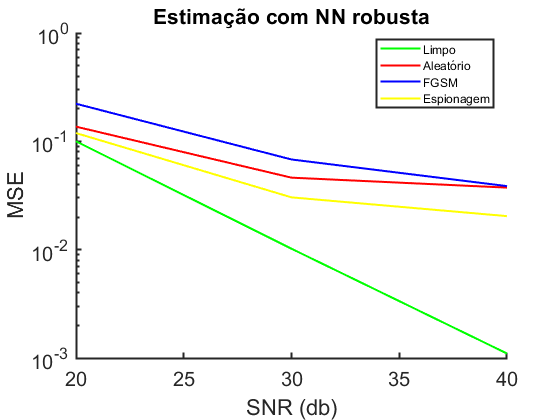

figure;
X = [20 30 40];
nn = [0.1 0.0102 0.0011];
nn_rand = [0.1366 0.0462 0.0374];
nn_fgsm = [0.2224 0.0680 0.0386];
nn_espio = [0.1192 0.0304 0.0204];

% Defina cores personalizadas para cada linha
cor_nn = 'g';         % Vermelho
cor_nn_rand = 'r'; 
cor_nn_fgsm = 'b'; 
cor_nn_espio = 'y'; 

figure;

% Plote as curvas com as cores personalizadas e escala logarítmica no eixo y
semilogy(X, nn, 'LineWidth', 1.5, 'Color', cor_nn);
hold on;
semilogy(X, nn_rand, 'LineWidth', 1.5, 'Color', cor_nn_rand);
semilogy(X, nn_fgsm, 'LineWidth', 1.5, 'Color', cor_nn_fgsm);
semilogy(X, nn_espio, 'LineWidth', 1.5, 'Color', cor_nn_espio);

t = title('Estimação com NN robusta');
t.FontSize = 16;

x = xlabel('SNR (db)');
x.FontSize = 16;

y = ylabel('MSE');
y.FontSize = 16;
ylim([10e-4 1])

% Aumente a espessura das linhas dos eixos
ax = gca;
ax.LineWidth = 1.5;

ax.XAxis.FontSize = 15;
ax.YAxis.FontSize = 15;


box off

% Adicione uma legenda
legend('Limpo', 'Aleatório', 'FGSM', 'Espionagem', 'Location', 'Best');

## 11 - SNR NN melhorada

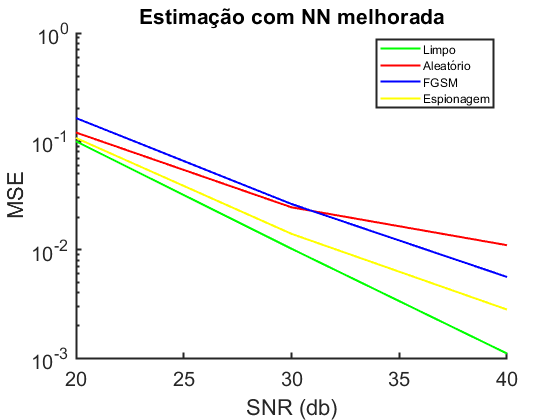

figure;
X = [20 30 40];
nn = [0.1 0.0102 0.0011];
nn_rand = [0.1206 0.0246 0.0110];
nn_fgsm = [0.1640 0.0264 0.0056];
nn_espio = [0.1074 0.0140 0.0028];

% Defina cores personalizadas para cada linha
cor_nn = 'g';         % Vermelho
cor_nn_rand = 'r'; 
cor_nn_fgsm = 'b'; 
cor_nn_espio = 'y'; 

figure;

% Plote as curvas com as cores personalizadas e escala logarítmica no eixo y
semilogy(X, nn, 'LineWidth', 1.5, 'Color', cor_nn);
hold on;
semilogy(X, nn_rand, 'LineWidth', 1.5, 'Color', cor_nn_rand);
semilogy(X, nn_fgsm, 'LineWidth', 1.5, 'Color', cor_nn_fgsm);
semilogy(X, nn_espio, 'LineWidth', 1.5, 'Color', cor_nn_espio);

t = title('Estimação com NN melhorada');
t.FontSize = 16;

x = xlabel('SNR (db)');
x.FontSize = 16;

y = ylabel('MSE');
y.FontSize = 16;
ylim([10e-4 1])

% Aumente a espessura das linhas dos eixos
ax = gca;
ax.LineWidth = 1.5;

ax.XAxis.FontSize = 15;
ax.YAxis.FontSize = 15;


box off

% Adicione uma legenda
legend('Limpo', 'Aleatório', 'FGSM', 'Espionagem', 'Location', 'Best');

## 12 - Variação da potência do FGSM

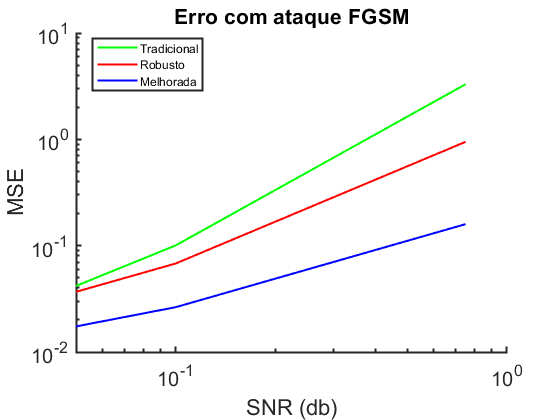

figure;
X = [0.05 0.1 0.75];
nn = [ 0.0209   0.0503    1.6494]*2;
nn_robust = [0.0184    0.0340    0.4740 ]*2;
nn_enhanced = [0.0087    0.0132    0.0797]*2;


% Defina cores personalizadas para cada linha
cor_nn = 'g';         % Vermelho
cor_nn_robust = 'r'; 
cor_nn_enhanced = 'b'; 

figure;

% Plote as curvas com as cores personalizadas e escala logarítmica no eixo y
loglog(X, nn, 'LineWidth', 1.5, 'Color', cor_nn);
hold on;
loglog(X, nn_robust, 'LineWidth', 1.5, 'Color', cor_nn_robust);
loglog(X, nn_enhanced, 'LineWidth', 1.5, 'Color', cor_nn_enhanced);

t = title('Erro com ataque FGSM');
t.FontSize = 16;

x = xlabel('SNR (db)');
x.FontSize = 16;

y = ylabel('MSE');
y.FontSize = 16;
ylim([10e-3 10])

% Aumente a espessura das linhas dos eixos
ax = gca;
ax.LineWidth = 1.5;

ax.XAxis.FontSize = 15;
ax.YAxis.FontSize = 15;


box off

% Adicione uma legenda
legend('Tradicional', 'Robusto', 'Melhorada', 'Location', 'Best');
hold off;